# Stance-Dynamics - Euler-Lagrange II

Dynamics of one-legged dodo-modell in stance-phase.

The following assumptions were made:

- Spring-force of leg is modelled as internal potential energy

- Contact with ground is ideal (e=1 for impulse)

- LOREM IPSUM

clear all;
clc;

## 1) Parameters

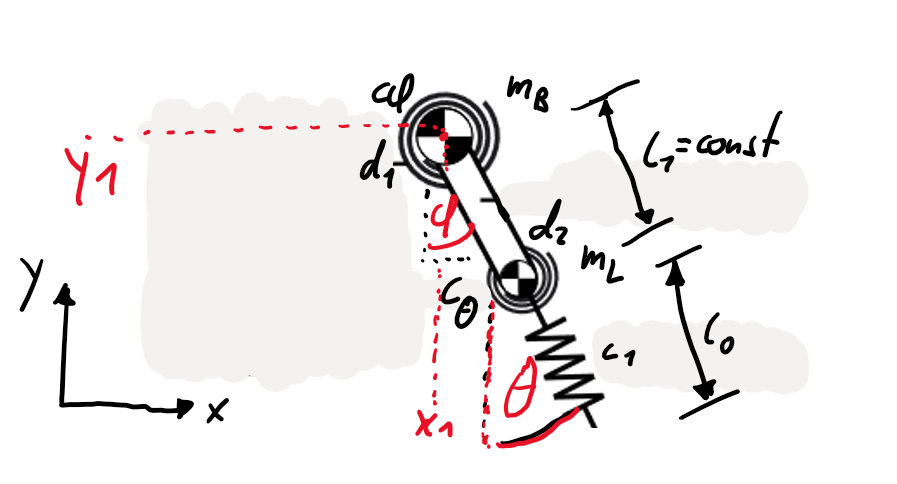

#### 1_1) Physical parameters

syms m_L; % kg; Mass of leg, concentrated as point mass in knee
syms m_B; % kg; Mass of upper body, concentrated as point mass in hip

syms d_1; % N*s/rad; Rotational damper in hip
syms d_2; % N*s/rad; Rotational damper in knee

syms c_phi; % N/rad; Rotational spring in hip
syms c_theta; % N/rad; Rotational spring in knee
syms c_1; % N/m; Translational spring attached to knee

syms l_1; % m, Length of leg-segment between knee and hip
syms l_0; % m, Initial length of translational spring at knee

syms g_earth;
g = [0; g_earth]; % m/s^2; Gravitational acceleration

#### 1_2) Dynamic parameters

syms t x_1(t) y_1(t) phi(t) theta(t);
q = [x_1; y_1; phi; theta]; % Vector of generalized coordinates, see picture for more information

syms dx_1(t) dy_1(t) dphi(t) dtheta(t); % Variables for velocity of generalized coordiantes, used later for Euler-Lagrange function
syms ddx_1 ddy_1 ddphi ddtheta; % Variables for acceleration of generalized coordiantes, used later for Euler-Lagrange function

## 2) Position vectors of point masses


r_mB = [x_1; y_1]; %Position of hip
r_mL = [x_1 + sin(phi)*l_1; y_1 - cos(phi)*l_1]; %Position of knee

%Velocity
d_r_mB = diff(r_mB);
d_r_mB = subs(d_r_mB, diff(x_1), dx_1);
d_r_mB = subs(d_r_mB, diff(y_1), dy_1);
d_r_mL = diff(r_mL);
d_r_mL = subs(d_r_mL, diff(x_1), dx_1);
d_r_mL = subs(d_r_mL, diff(y_1), dy_1);
d_r_mL = subs(d_r_mL, diff(phi), dphi);
d_r_mL = subs(d_r_mL, diff(theta), dtheta);

## 3) Terms for Euler-Lagrange

#### 3_1) Kinetic_Energy

T_B = 0.5 * m_B * (d_r_mB' * d_r_mB); % Kinetic energy of hip

T_L = 0.5 * m_L * (d_r_mL' * d_r_mL); % Kinetic energy of knee

T = T_B + T_L; % Total kinetic energy

#### 3_2) Potential_Energy

V_G = - m_B * (r_mB' * g) - m_L * (r_mL' * g); % Gravitational potential energy

V_rotC = c_phi * phi + c_theta * theta; % Rotational spring energy

l = sqrt(r_mL' * r_mL); % m; current length of translational spring
V_c = c_1 * (l - l_0); % Translational spring energy

V = simplify(V_G + V_rotC + V_c); % Total potential energy

#### 3_3) Non-conservative forces

X_1 = -d_1 * diff(phi) * [-cos(phi); - sin(phi)];
X_2 = -d_2 * diff(theta) * [-cos(theta); - sin(theta)];

%Help variables for calculating the differentiations
xx = sym('x_1');
yy = sym('y_1');
phiphi = sym('phi');
thetatheta = sym('theta');

dx_r_mB = subs(diff(subs(r_mB,x_1,xx),xx),xx,x_1);
dx_r_mL = subs(diff(subs(r_mL,x_1,xx),xx),xx,x_1);

dy_r_mB = subs(diff(subs(r_mB,y_1,yy),yy),yy,y_1);
dy_r_mL = subs(diff(subs(r_mL,y_1,yy),yy),yy,y_1);

dphi_r_mB = subs(diff(subs(r_mB,phi,phiphi),phiphi),phiphi,phi);
dphi_r_mL = subs(diff(subs(r_mL,phi,phiphi),phiphi),phiphi,phi);

dtheta_r_mB = subs(diff(subs(r_mB,theta,thetatheta),thetatheta),thetatheta,theta);
dtheta_r_mL = subs(diff(subs(r_mL,theta,thetatheta),thetatheta),thetatheta,theta);


Q_nc_x = (dx_r_mB)' * X_1 + (dx_r_mL)' * X_2;
Q_nc_y = (dy_r_mB)' * X_1 + (dy_r_mL)' * X_2;
Q_nc_phi = (dphi_r_mB)' * X_1 + (dphi_r_mL)' * X_2;
Q_nc_theta = (dtheta_r_mB)' * X_1 + (dtheta_r_mL)' * X_2;

Q_nc = [Q_nc_x; Q_nc_y; Q_nc_phi; Q_nc_theta]; %Vector of non-conservative forces
%Adjusting Q
Q_nc = subs(Q_nc, diff(x_1), dx_1);
Q_nc = subs(Q_nc, diff(y_1), dy_1);
Q_nc = subs(Q_nc, diff(phi), dphi);
Q_nc = subs(Q_nc, diff(theta), dtheta);

## 4) Building Lagrange-Function

%%Building the Lagrange-Function

%Calculatin dt_ddq_T
ddq_T = functionalDerivative(T, [dx_1;dy_1;dphi;dtheta]);

dt_ddq_T = diff(ddq_T);

%Calculating dT/dq
dq_T = functionalDerivative(T, [x_1;y_1;phi;theta]);

%Calculatin dV/dq
dq_V = functionalDerivative(V, [x_1;y_1;phi;theta]);


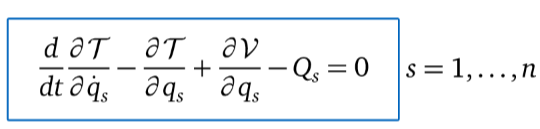

lagrange = dt_ddq_T - dq_T + dq_V - Q_nc;

## 5) Applying Euler-Lagrange II


eqn = lagrange == zeros(4,1);

X = [ddx_1; ddy_1; ddphi; ddtheta]; %Acceleration-State-Vector

%Substituting the time-dependent variables and their differentiations

eqn = subs(eqn,diff(dx_1), ddx_1);
eqn = subs(eqn,diff(dy_1), ddy_1);
eqn = subs(eqn,diff(dphi), ddphi);
eqn = subs(eqn,diff(dtheta), ddtheta);

sol = solve(eqn,X)

sol = struct with fields:
      ddx_1: [0×1 sym]
      ddy_1: [0×1 sym]
      ddphi: [0×1 sym]
    ddtheta: [0×1 sym]
